# Symbolic calculations

syms x y gamma
f = x.^2 + x.*y + 10 * y.^2 - 22 .* y - 5 .* x

$$f = x^{2}+x\,y-5\,x+10\,y^{2}-22\,y$$

grad_f = gradient(f)

$$grad\_f = \left(\begin{array}{c} 2\,x+y-5\\ x+20\,y-22 \end{array}\right)$$

new_xy = [x;y] - gamma * grad_f

$$new\_xy = \left(\begin{array}{c} x-\gamma \,\left(2\,x+y-5\right)\\ y-\gamma \,\left(x+20\,y-22\right) \end{array}\right)$$


f(x,y) = f

$$f(x, y) = x^{2}+x\,y-5\,x+10\,y^{2}-22\,y$$

grad_f(x,y) = grad_f

$$grad\_f(x, y) = \left(\begin{array}{c} 2\,x+y-5\\ x+20\,y-22 \end{array}\right)$$

g(x,y,gamma) = simplify(f(new_xy(1),new_xy(2)))

$$g(x, y, gamma) = 5\,\gamma \,\left(2\,x+y-5\right)-22\,y-5\,x+22\,\gamma \,\left(x+20\,y-22\right)+{\left(x-\gamma \,\left(2\,x+y-5\right)\right)}^{2}+10\,{\left(y-\gamma \,\left(x+20\,y-22\right)\right)}^{2}+\left(x-\gamma \,\left(2\,x+y-5\right)\right)\,\left(y-\gamma \,\left(x+20\,y-22\right)\right)$$

g_diff(gamma)=simplify(diff(g,gamma))

$$g\_diff(gamma) = 9950\,\gamma +64\,x+890\,y-1018\,\gamma \,x-17864\,\gamma \,y-44\,x\,y+32\,\gamma \,x^{2}+8042\,\gamma \,y^{2}-5\,x^{2}-401\,y^{2}+890\,\gamma \,x\,y-509$$

gamma_opt(x,y) = simplify(solve(g_diff,gamma))

$$gamma\_opt(x, y) = \frac{5\,x^{2}+44\,x\,y-64\,x+401\,y^{2}-890\,y+509}{32\,x^{2}+890\,x\,y-1018\,x+8042\,y^{2}-17864\,y+9950}$$

## Calculations

max_iterations = 200;
error = 1e-12;
points = zeros([2,max_iterations]);
values = zeros([1,max_iterations]);
%p = (rand(2,1)-0.5) * 20
p = [10;1]

p =     10
     1


points(:,1) = p;
gamma_0 = 0

gamma_0 = 0

grad = 0 

grad = 0

for k=1:max_iterations
    points(:,k+1) = p;
    gamma_0 = double(gamma_opt(p(1),p(2)));
    grad = double(grad_f(p(1),p(2)));
    p = p - gamma_0 * grad;
    values(k) = double(f(p(1),p(2)));
    if (norm(grad) < error)
        break
    end
end

## Plots

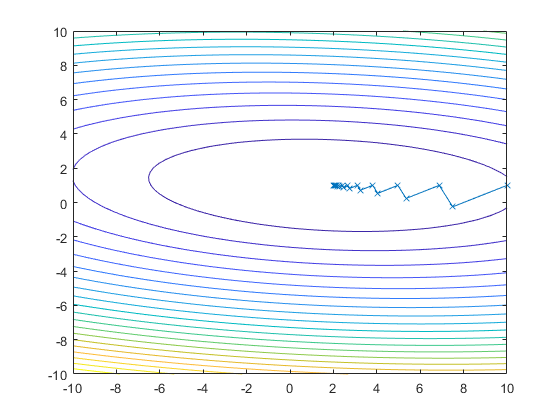

[X,Y] = meshgrid(-10:0.25:10);
F = double(f(X,Y));
figure(1); contour(X,Y,F,20); hold on; 
plot3(points(1,1:k),points(2,1:k),values(1:k), '-x'); hold off;